# Spline cúbico (funcion de Matlab)

% spline

% puntos entre puntos via
num=20;
stheta1 = spline(1:length(theta1),[0,theta1,0],linspace(1,length(theta1),length(theta1)*num));
stheta2 = spline(1:length(theta2),[0,theta2,0],linspace(1,length(theta2),length(theta1)*num));



## Obtención de trayectoria suave

Nota: considerece las unidades del tiempo adimencionales, para calculos de velocidad y aceleracion por aproximación de euler también.

en caso de querer considerar, dividir sobre la separación entre datos o multiplicar sobre la cantidad de datos (tamaño_de_vector/rango).

ej: variable "factor"

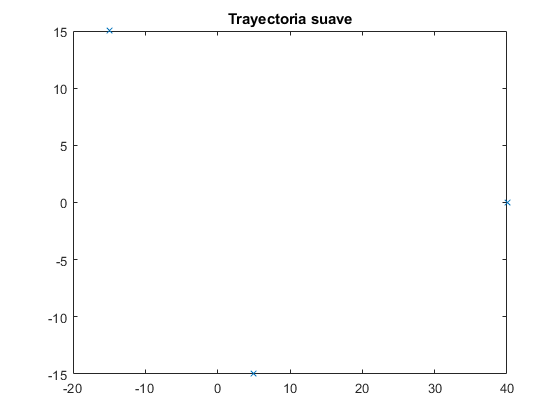

% par animacion ejecutar en Command Windows
% DirectaRR(stheta1,stheta2)
plot(PuntosC(1:2:end),PuntosC(2:2:end),'x')
title('Trayectoria suave')
hold off

## Espacio de configuración

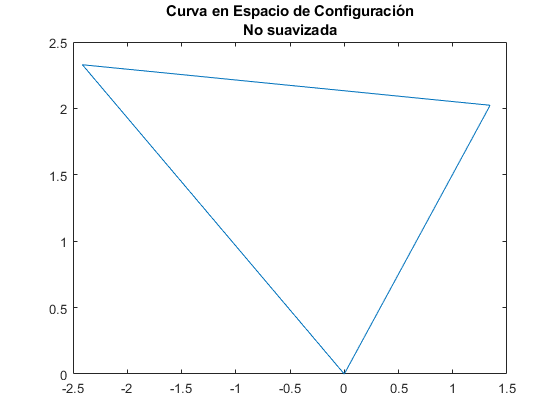

% antes spline
plot(theta1,theta2)
title({'Curva en Espacio de Configuración';'No suavizada'})

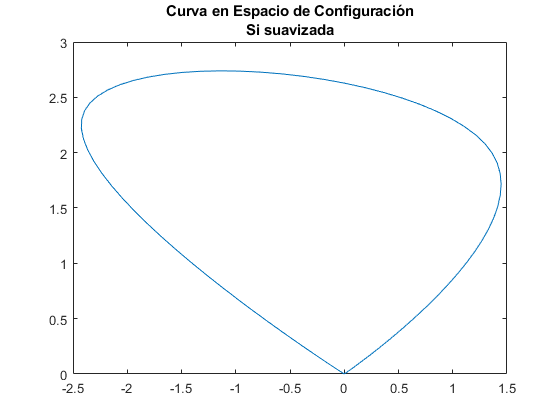


% despues de spline
plot(stheta1,stheta2)
title({'Curva en Espacio de Configuración';'Si suavizada'})

## Theta1 en el tiempo

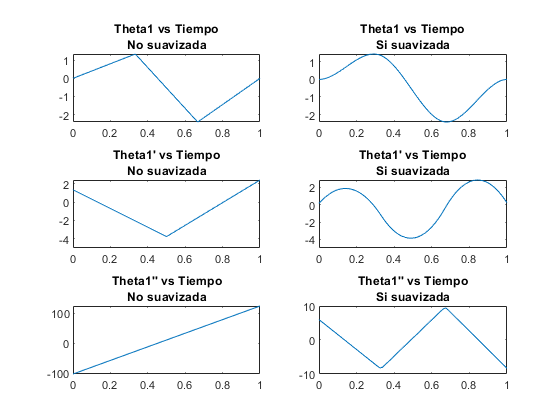

subplot(3,2,1);
% Posicion theta1 respecto al tiempo
% antes
plot(linspace(0,1,length(theta1)),theta1)
title({'Theta1 vs Tiempo';'No suavizada'})
subplot(3,2,2);
% despues de spline
plot(linspace(0,1,length(stheta1)),stheta1)
title({'Theta1 vs Tiempo';'Si suavizada'})
subplot(3,2,3);

% velocidad respecto al tiempo theta1
% antes de spline
factor=length(theta1)/length(stheta1);
theta1_prima1=diff(theta1);
plot(linspace(0,1,length(theta1_prima1)),theta1_prima1)
title({"Theta1' vs Tiempo";'No suavizada'})
subplot(3,2,4);
% despues de spline
stheta1_prima1=diff(stheta1)/factor;
plot(linspace(0,1,length(stheta1_prima1)),stheta1_prima1)
title({"Theta1' vs Tiempo";'Si suavizada'})
subplot(3,2,5);
% aceleracion respecto al tiempo theta1
% antes de spline
theta1_prima2=diff(theta1_prima1)/factor;
plot(linspace(0,1,length(theta1_prima2)),theta1_prima2)
title({"Theta1'' vs Tiempo";'No suavizada'})
subplot(3,2,6);
% despues de spline
stheta1_prima2=diff(stheta1_prima1)/factor;
plot(linspace(0,1,length(stheta1_prima2)),stheta1_prima2)
title({"Theta1'' vs Tiempo";'Si suavizada'})


% Programado por: Alfredo José Maussa Caballero.